# Validate forced alignment: A Demo

Written by Chloe D. Kwon

June 3, 2025

This live script demonstrates how to validate the quality of the forced-alignment data from the [validate-forced-alignment repo](https://github.com/chloedkkwon/validate-forced-alignment).

## What is foced alignment?

**Forced alignment** refers to a method used to automatically match spoken audio to written text. Imagine you have a recording of someone reading a sentence aloud. Forced alignment figures out when each word or sound starts and ends in that recording. 

This technique is widely used in** linguistic research**, especially in phonetics and phonology, to analyze how speech sounds are produced across different speakers and contexts. It's also a valuable tool in **speech technology**: it helps improve voice recognition systems, train speech synthesis models, and create accurate, time-aligned subtitles or transcripts for applications like virtual assistants, audiobooks, and language learning tools.

## Why validate foced alignment?

Forced alignment is useful, but it's not perfect. The aligner model guesses where each soud begins and ends based on the audio and transcript, but sometimes it makes mistakes, especially when the speech is fast, unclear, or hasbackground noise. In some cases, the alignmer may even produce completely incorrect results.

By validating the data, we can measure how well the aligner is doing and make improvements if needed. It's a quality chekc that helps ensure our alignment results are reliable and trustworthy. 

## How do we validate?

One way to do it is comparing the automatically generated boundaries of sounds and words from forced alignment to manually labeled boundaries created by a trained annotator. By measuring the differences between the two (i.e., how far off the aligner's timing is from the manual labels) we can quantify the aligner's accuracy. This helps us identify patterns in the errors and understand which types of sounds or contexts are more prone to mistakes. The goal is to ensure that the alignments are reliable enough for research or application use.

## Where do I start?

First, download or clone [the repository](https://github.com/chloedkkwon/validate-forced-alignment), then run the `run.m` script. By default, it uses the sample data provided in the `./sample_data` folder. If you’d like to use your own data, you’ll need at least one audio file and two corresponding TextGrid files: one with manual alignments and one with automatic alignments. Be sure to update the directory paths in `run.m` to point to your own files.

After you've run the script, you should get several output files in .mat format. There should be one for your sounds or phones in `phoneTier`.mat and one for your words in `wordTier.mat`. 

%Load word alignment info
wordDataPath = 'wordTier.mat'; 
wordDataStruct = load(wordDataPath);
W = wordDataStruct.W;
disp(W)

  5×1 struct array with fields:

    fname
    wordTier_manual
    wordTier_auto
    wordTier_comprison



% Load phone alignment info
phoneDataPath = 'phoneTier.mat'; 
phoneDataStruct = load(phoneDataPath);
P = phoneDataStruct.P;
disp(P)

  5×1 struct array with fields:

    fname
    phoneTier_manual
    phoneTier_auto
    phoneTier_comparison



Note that both `W` and `P`, our structs with word and phone alignment information, have the same structure. They both have embedded tables inside each field (columns) other than `fname` (i.e., filename). The field with the suffix `_comparison` is the one that shows the boundary deviations between manual and automatic labels in milliseconds.

disp(W(1).wordTier_comprison)

           boundaries           dev    label_changed
    ________________________    ___    _____________

    {'SIL yeongmineun'     }     6           0      
    {'yeongmineun deulpane'}    -4           0      
    {'deulpane isseo'      }     2           0      
    {'isseo SIL'           }     2           0      



The column `dev` shows how far off the automatically created labels' boundaries are from the manually created one in milliseconds. `label_changed` checks whether the aligner assigned a label different from the manual label.

## Visual inspection of manual vs. auto-alignment

Visual inspection should always precede quantitative analysis, as it allows researchers to catch obvious errors that automated metrics might miss. It also helps develop an intuition for what to expect from the quantitative results, serving as an additional check on the quality of the alignment. 

With that in mind, let’s use the tables to visualize the differences in alignment labels.

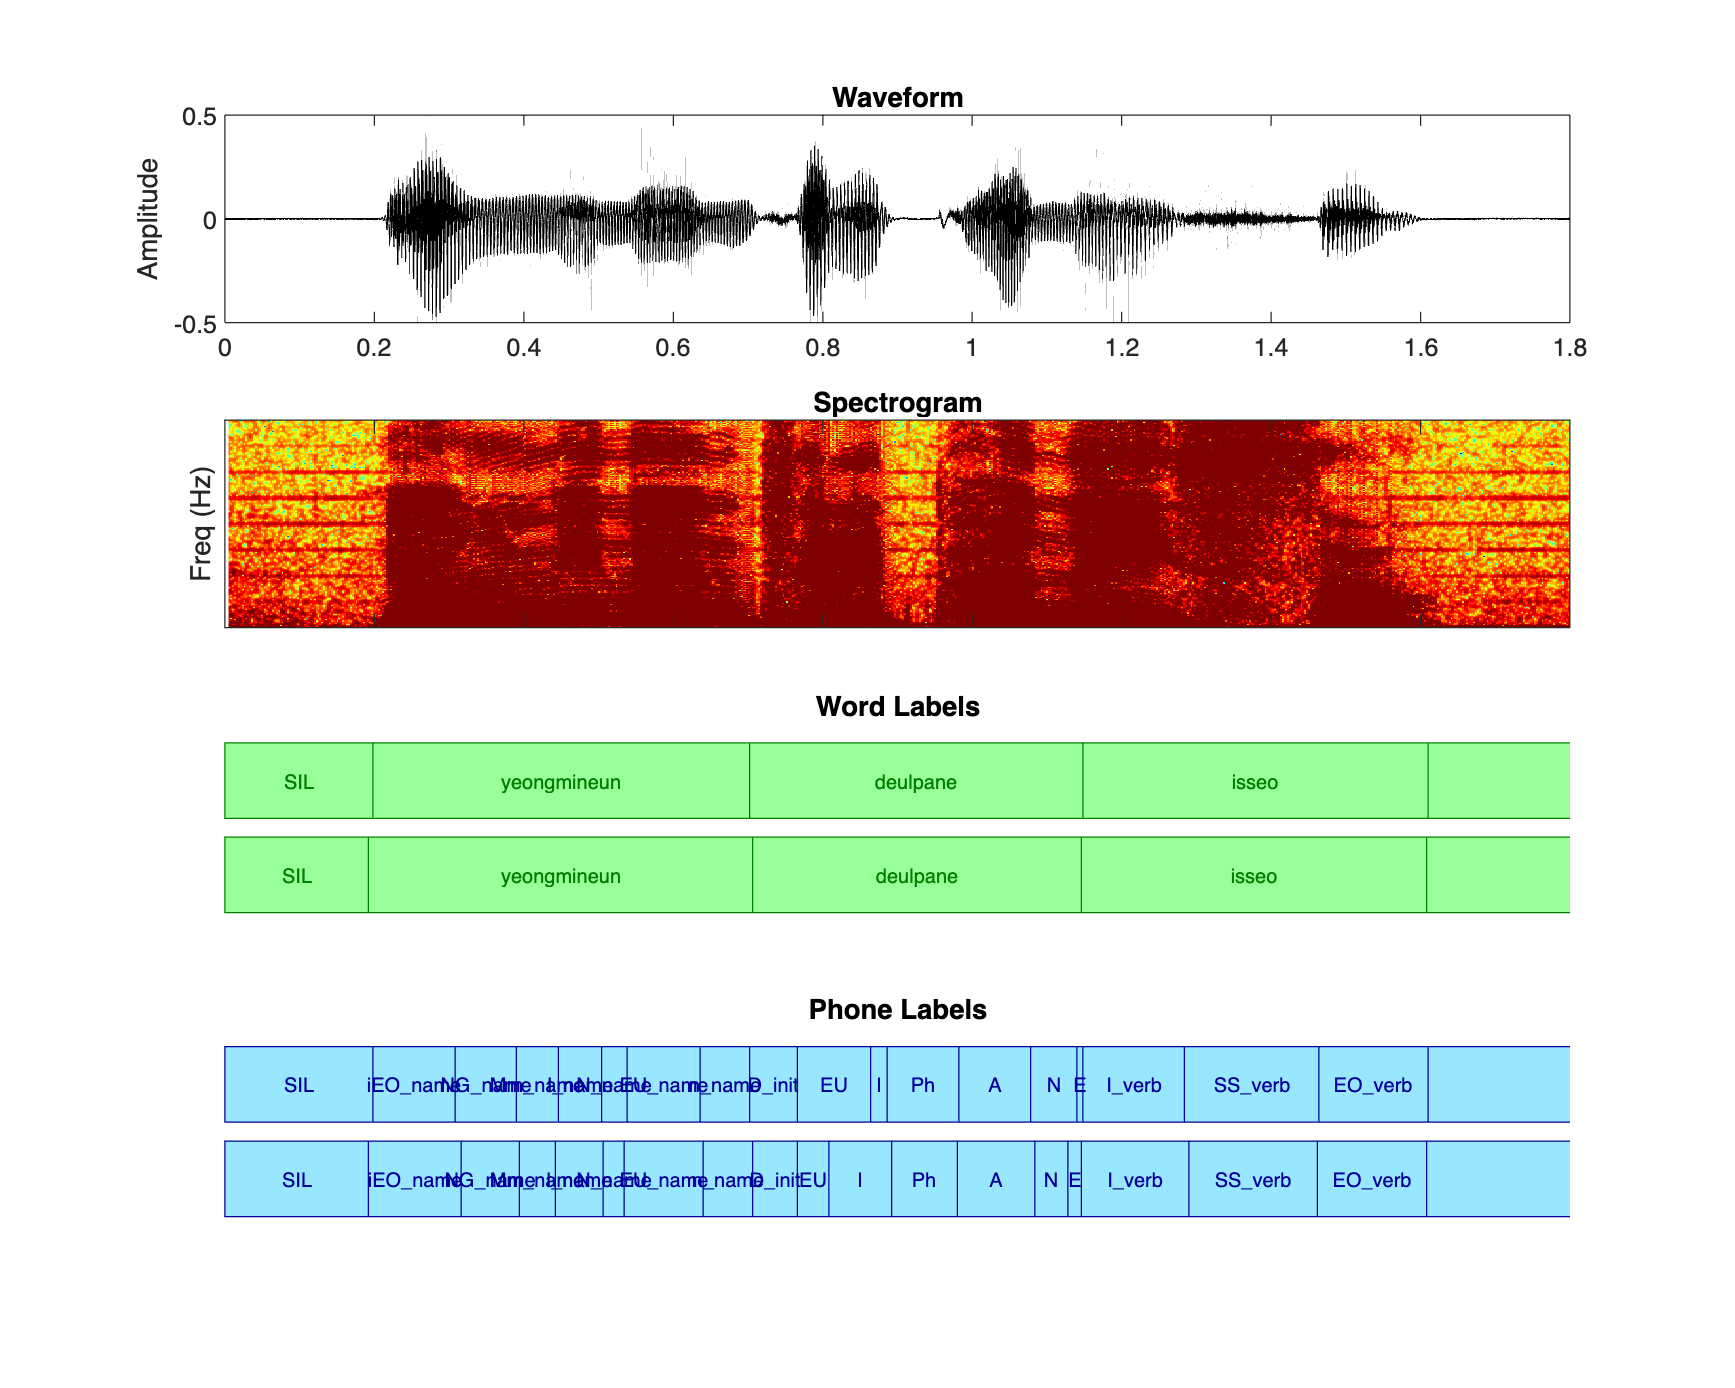

% Load audio file
[audio, fs] = audioread(fullfile('sample_data', 'audio', 'F04_03_028.wav')); 
t = linspace(0, length(audio)/fs, length(audio)); % time vector

% Find the corresponding labels
fnames = {P.fname}; 
file_ix = find(strcmp(fnames, 'F04_03_028.TextGrid')); 

% Labels from manual alignment
word_labels_manual = W(file_ix).wordTier_manual; 
phone_labels_manual = P(file_ix).phoneTier_manual; 

% Labels from auto alignment
word_labels_auto = W(file_ix).wordTier_auto; 
phone_labels_auto = P(file_ix).phoneTier_auto; 

% Convert back to sec
word_labels_manual.t0 = word_labels_manual.t0 / 1000;
word_labels_manual.t1 = word_labels_manual.t1 / 1000;

word_labels_auto.t0 = word_labels_auto.t0 / 1000;
word_labels_auto.t1 = word_labels_auto.t1 / 1000;

phone_labels_manual.t0 = phone_labels_manual.t0 / 1000;
phone_labels_manual.t1 = phone_labels_manual.t1 / 1000;

phone_labels_auto.t0 = phone_labels_auto.t0 / 1000;
phone_labels_auto.t1 = phone_labels_auto.t1 / 1000;

% Helper functions
% Draw label rectangles (with edges)
plot_labels = @(labels, y_base, box_height, faceColor, edgeColor) ...
    arrayfun(@(i) rectangle('Position', ...
        [labels.t0(i), y_base, labels.t1(i) - labels.t0(i), box_height], ...
        'FaceColor', [faceColor, 0.4], ...
        'EdgeColor', edgeColor, ...
        'LineWidth', 0.5), ...
        1:height(labels));

% Draw text inside boxes
label_text = @(labels, y_base, box_height, color) ...
    arrayfun(@(i) text( ...
        (labels.t0(i) + labels.t1(i)) / 2, ... % horizontal center
        y_base + box_height / 2, ...           % vertical center
        string(labels.label(i)), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle', ...
        'FontSize', 8, ...
        'Color', color, ...
        'Interpreter', 'none'), ...            % <-- disables LaTeX
        1:height(labels));

% Create figure
figure('Position', [100, 100, 1000, 800]);

% --- Row 1: Waveform ---
subplot(4,1,1);
plot(t, audio, 'k');
xlim([0 1.8]);
ylabel('Amplitude');
title('Waveform');
%set(gca, 'XTickLabel', []);

% --- Row 2: Spectrogram ---
subplot(4,1,2);

% Parameters
window = 256;
noverlap = 200;
nfft = 512;

% Compute spectrogram
[S, F, Tspec] = spectrogram(audio, window, noverlap, nfft, fs);
S_dB = 20*log10(abs(S) + eps); % convert to dB

% Plot using imagesc (not spectrogram())
imagesc(Tspec, F, S_dB);
axis xy;
colormap(jet);
caxis([-100 -30]); % dB range
ylim([0 8000]);
xlim([0 1.8]);

% Clean up axes
set(gca, 'XTickLabel', []); 
set(gca, 'YTick', []);
ylabel('Freq (Hz)');
title('Spectrogram');

% --- Row 3: Manual vs. Auto in word tier ---
subplot(4,1,3);
hold on;

% Parameters
box_height = 0.4;

plot_labels(word_labels_manual, 0.1, box_height, [0.6 1 0.6], [0 0.5 0]);
plot_labels(word_labels_auto, 0.6, box_height, [0.6 1 0.6], [0 0.5 0]);

label_text(word_labels_manual, 0.1, box_height, [0 0.5 0]);
label_text(word_labels_auto, 0.6, box_height, [0 0.5 0]);

xlim([0 1.8]);
ylim([0 1.1]);
title('Word Labels');
set(gca, 'YTick', []);
set(gca, 'XTick', []);
set(gca, 'XTickLabel', []);
set(gca, 'XColor', 'none');
set(gca, 'YColor', 'none');

% --- Row 4: Manual vs. Auto labels in phone tier ---
subplot(4,1,4);
hold on;

% Parameters
box_height = 0.4;

plot_labels(phone_labels_manual, 0.1, box_height, [0.6 0.9 1], [0 0 0.6]);
label_text(phone_labels_manual, 0.1, box_height, [0 0 0.6]);

plot_labels(phone_labels_auto, 0.6, box_height, [0.6 0.9 1], [0 0 0.6]);
label_text(phone_labels_auto, 0.6, box_height, [0 0 0.6]);

xlim([0 1.8]);
ylim([0 1.1]);
title('Phone Labels');
set(gca, 'YTick', []);
set(gca, 'XTick', []);
set(gca, 'XColor', 'none');
set(gca, 'YColor', 'none');

Note that most of it looks fine. For example, the word alignments look similar to one another, and the phone alignments are similar within the first word, *yeongmineun*. However, if you look closely, there's a pattern of the aligner struggling to detect where the boundary falls between a vowel and another sonorous sound (e.g., EU and L in this token). Let's see if this is true across tokens by quantifying the deviations between labels. 

## Using deviations to analyze manual vs. auto-alignment

% Get aggregated tables for each tier
word_boundaries = vertcat(W.wordTier_comprison); 
phone_boundaries = vertcat(P.phoneTier_comparison); 

% Group by 'boundaries'
[G, boundary_names] = findgroups(word_boundaries.boundaries);

[word_agg] = aggregate_boundaries(word_boundaries);
[phone_agg] = aggregate_boundaries(phone_boundaries); 

% Sort
word_agg = sortrows(word_agg, 'dev_sum', 'descend')

word_agg = 16×3 table
          boundaries          dev_sum    label_changed_sum
    ______________________    _______    _________________

    "haesseo SIL"               20               0        
    "jinhoneun apnali"          10               0        
    "SIL yeongmineun"            6               0        
    "isseo SIL"                  6               0        
    "apnali isseo"               4               0        
    "yeongmineun deulpane"       4               0        
    "SIL eununeun"               2               0        
    "SIL jinhoneun"              2               0        
    "deulpane isseo"             2               0        
    "SIL minaneun"               0               0        
    "eununeun gadameul"          0               0        
    "gadameul haesseo"           0               0        
    "joahae SIL"                 0               

phone_agg = sortrows(phone_agg, 'dev_sum', 'descend')

phone_agg = 59×3 table
        boundaries        dev_sum    label_changed_sum
    __________________    _______    _________________

    "U_name EU_name"      68.283             0        
    "EU l"                    56             0        
    "M EU"                    52             1        
    "N_name O_name"           42             0        
    "O_name N_name"           36             1        
    "EO_verb SIL"             26             0        
    "EU R"                    14             0        
    "N E"                     12             0        
    "SS_verb EO_verb"          8             0        
    "iEO_name NG_name"         8             0        
    "m Nn"                     8             0        
    "A N"                      6             0        
    "I_verb SS_verb"           6             0        
    "N_name EU_name"           6             0   

It appears that for words, the largest deviations tend to occur at sentence-initial or sentence-final boundaries. However, even the highest deviations amount to only about 20 ms in total, which is relatively minor for word-level segmentation.But phone-level deviations are generally larger and more problematic, particularly at boundaries between two sonorous sounds such as vowels, liquids (e.g., /l/, /r/), and nasals (e.g., /m/, /n/). Based on this pattern, a useful next step would be to augment the training data with additional examples containing these challenging boundaries to evaluate whether doing so improves the overall alignment accuracy.

## Some analysis ideas

- Classify individual phonemes into sound classes (e.g., nasals, liquids) and see what sound sequences are most problematic. 

- Analyze by word position -- which phonemes in which words are most problematic? Does it have to do with specific word type or the position of the word?

- Examine how consistently certain boundaries show large deviations, especially across speakers or words.

- Sum or average deviations per sentence or utterance to get a global measure of alignment quality. 

Forced alignment, although tedious, is a necessary step in speech analysis, especially if you are looking into fine-grained acoustic measurements. It's also essential to ensure data quality and consistency through validation steps. I hope this mini-guide offers a helpful starting point for exploring and improving your own alignment workflows.

**Helper function for aggregated boundaries**

function T_agg = aggregate_boundaries(T)
%AGGREGATE_BOUNDARIES Aggregates rows with the same 'boundaries'
%   Input:  T — table with variables:
%              - boundaries (string or cellstr)
%              - dev (numeric)
%              - label_changed (binary or numeric)
%   Output: T_agg — aggregated table with:
%              - boundaries
%              - dev_sum (sum of abs(dev))
%              - label_changed_sum

    % Ensure boundaries are strings for consistent grouping
    if iscell(T.boundaries)
        T.boundaries = string(T.boundaries);
    end

    % Group and aggregate
    [G, boundary_names] = findgroups(T.boundaries);
    agg_dev = splitapply(@(x) sum(abs(x)), T.dev, G);
    agg_changed = splitapply(@sum, T.label_changed, G);

    % Return aggregated table
    T_agg = table();
    T_agg.boundaries = boundary_names;
    T_agg.dev_sum = agg_dev;
    T_agg.label_changed_sum = agg_changed;
end